clear
clf
%Problem 2

a = 1.115 * 10^-3; %Thermal diffusivity(m^2/s)
U = 100; %Initial temperature (K)
u_o = 50;
u_L = 50;
L = 1; %Length of the domain (m)
q = 1;
c = 1;
x = linspace(0,1,1000);
t = 0;
theta = 0;
%Transient part
for i = 1:100000
lam = i*pi/L;
b_1 = ((U-u_o)/lam)*(1-cos(lam*L));
b_2 = (((u_L-u_o)/L)+((q*L)/(2*a*c)))*((sin(lam*L)/(lam^2))-((L*cos(lam*L))/(lam)));
b_3 = (q/(2*a*c))*((((L^2)*(cos(lam*L)))/(lam))-((2*L*sin(lam*L))/(lam^2))-((2*cos(lam*L))/(lam^3))+((2/(lam^3))));
b_n = b_1 - b_2 - b_3;
e = exp((-a*t).*(lam^2));
s = sin(lam.*x);
theta = theta + (b_n.*e.*s);
end

%Steady state part
u_s = u_o + ((u_L-u_o)/L).*(x) + (((x.*q)/(2*a*L)).*(L-x));

%Total solution
U = theta + u_s;

t_2 = 10;
theta_2 = 0;
%Transient part
for j = 1:100000
lam_2 = j*pi/L;
b_1_2 = ((U-u_o)/lam_2)*(1-cos(lam_2*L));
b_2_2 = (((u_L-u_o)/L)+((q*L)/(2*a*c)))*((sin(lam_2*L)/(lam_2^2))-((L*cos(lam_2*L))/(lam_2)));
b_3_2 = (q/(2*a*c))*((((L^2)*(cos(lam_2*L)))/(lam_2))-((2*L*sin(lam_2*L))/(lam_2^2))-((2*cos(lam_2*L))/(lam_2^3))+((2/(lam_2^3))));
b_n_2 = b_1_2 - b_2_2 - b_3_2;
e_2 = exp((-a*t_2).*(lam_2^2));
s_2 = sin(lam_2.*x);
theta_2 = theta_2 + (b_n_2.*e_2.*s_2);
end

%Total solution
U_2 = theta_2 + u_s;

t_3 = 100;
theta_3 = 0;
%Transient part
for k = 1:100000
lam_3 = k*pi/L;
b_1_3 = ((U-u_o)/lam_3)*(1-cos(lam_3*L));
b_2_3 = (((u_L-u_o)/L)+((q*L)/(2*a*c)))*((sin(lam_3*L)/(lam_3^2))-((L*cos(lam_3*L))/(lam_3)));
b_3_3 = (q/(2*a*c))*((((L^2)*(cos(lam_3*L)))/(lam_3))-((2*L*sin(lam_3*L))/(lam_3^2))-((2*cos(lam_3*L))/(lam_3^3))+((2/(lam_3^3))));
b_n_3 = b_1_3 - b_2_3 - b_3_3;
e_3 = exp((-a*t_3).*(lam_3^2));
s_3 = sin(lam_3.*x);
theta_3 = theta_3 + (b_n_3.*e_3.*s_3);
end

%Total solution
U_3 = theta_3 + u_s;

t_4 = 1000;
theta_4 = 0;
%Transient part
for l = 1:100000
lam_4 = l*pi/L;
b_1_4 = ((U-u_o)/lam_4)*(1-cos(lam_4*L));
b_2_4 = (((u_L-u_o)/L)+((q*L)/(2*a*c)))*((sin(lam_4*L)/(lam_4^2))-((L*cos(lam_4*L))/(lam_4)));
b_3_4 = (q/(2*a*c))*((((L^2)*(cos(lam_4*L)))/(lam_4))-((2*L*sin(lam_4*L))/(lam_4^2))-((2*cos(lam_4*L))/(lam_4^3))+((2/(lam_4^3))));
b_n_4 = b_1_4 - b_2_4 - b_3_4;
e_4 = exp((-a*t_4).*(lam_4^2));
s_4 = sin(lam_4.*x);
theta_4 = theta_4 + (b_n_4.*e_4.*s_4);
end

%Total solution
U_4 = theta_4 + u_s;

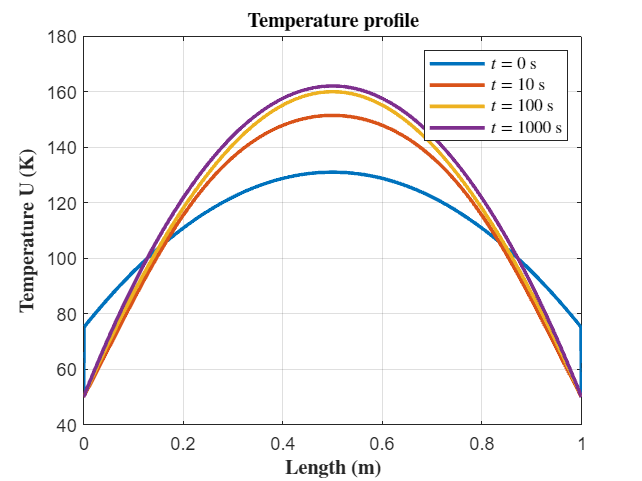

%Plots
h1 = plot(x,U,'LineWidth',2);
grid on
ylabel('$\textbf{Temperature U (K)}$','Interpreter', 'latex')
xlabel('$\textbf{Length (m)}$', 'Interpreter', 'latex')
title('$\textbf{Temperature profile}$', 'Interpreter', 'latex');
hold on
h2 = plot(x,U_2,'LineWidth',2);
h3 = plot(x,U_3,'LineWidth',2);
h4 = plot(x,U_4,'LineWidth',2);
legend([h1, h2, h3, h4], {'$t = 0$ s', '$t = 10$ s', '$t = 100$ s', '$t = 1000$ s'}, 'Interpreter', 'latex');

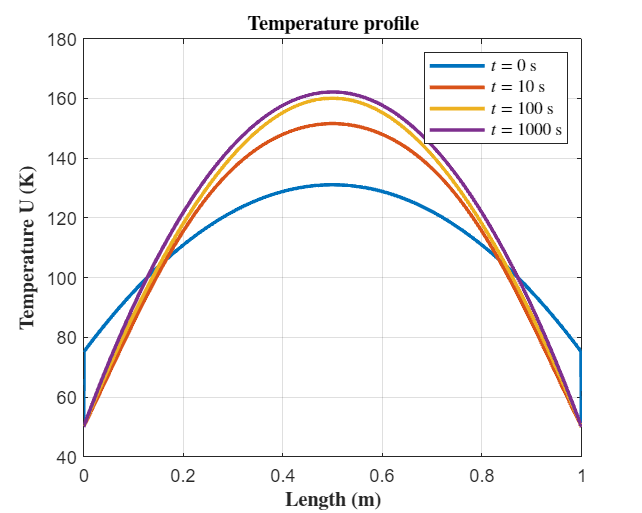

%Saving plot
outputFileName = 'Problem_2.png';
figureHandle = gcf;
figureWidth = 1000; % in pixels
figureHeight = 800; % in pixels
set(figureHandle, 'Position', [100, 100, figureWidth, figureHeight]); 
print(figureHandle, outputFileName, '-dpng', '-r600');